https://www.mathworks.com/help/symbolic/solve-differential-equation-numerically-1.html

syms y(t)
[V] = odeToVectorField(diff(y, 2) == (1 - y^2)*diff(y) - y)

$$V = \left(\begin{array}{c} Y_{2}\\ -\left({Y_{1}}^{2}-1\right)\,Y_{2}-Y_{1} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-(Y(1).^2-1.0).*Y(2)-Y(1)]


sol = ode45(M,[0 20],[2 0]);
fplot(@(x)deval(sol,x,1), [0, 20])

applying classic spring damper model

syms y(t)
%constants
k = 1; %spring
c = 1; %damper
m = 1; %mass
[V] = odeToVectorField(-m*diff(y, 2) == c*diff(y) + k*y)

$$V = \left(\begin{array}{c} Y_{2}\\ -Y_{1}-Y_{2} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)-Y(2)]


sol = ode45(M,[0 20],[0 2]);
fplot(@(x)deval(sol,x,1), [0, 20])

confirm by solving mathematically by hand

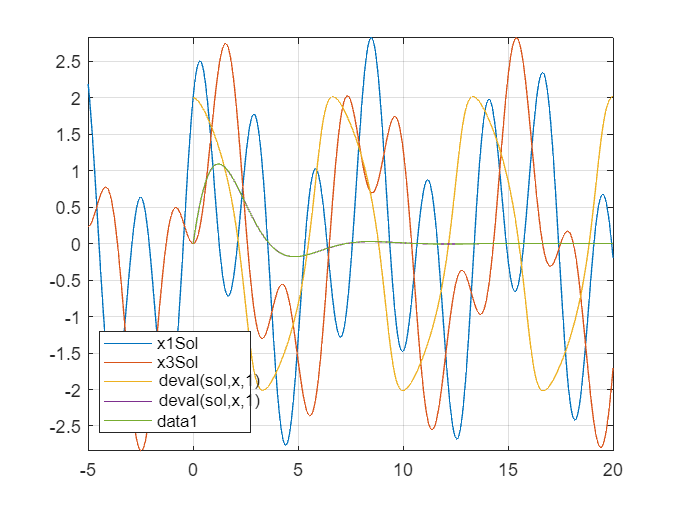

x = linspace(0,20,10000);
y = (4/sqrt(3))*exp(-1/2.*x).*sin(x.*sqrt(3)/2);
plot(x,y)

2 DOF spring sys (https://www.mathworks.com/help/symbolic/solve-a-system-of-differential-equations.html#SolveASystemOfDifferentialEquationsExample-2)

m = 1;
k = 2; %why are these not used????
syms x(t) y(t)
A = [-4 2; 2 -2];
Y = [x; y];
odes = diff(Y,2) == A*Y

$$odes(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=2\,y\left(t\right)-4\,x\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=2\,x\left(t\right)-2\,y\left(t\right) \end{array}\right)$$

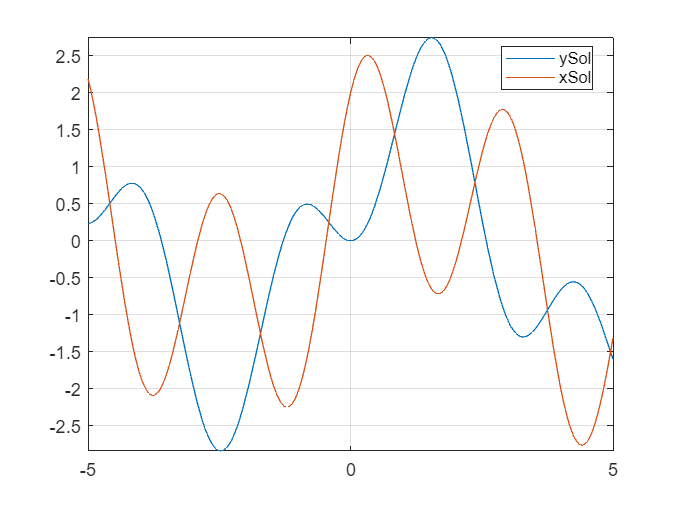

D = diff(Y);
C = [Y(0) == [2;0;],D(0) == [3;0]];
[xSol(t),ySol(t)] = dsolve(odes,C);
xSol(t) = simplify(xSol(t));
ySol(t) = simplify(ySol(t));
clf
fplot(ySol)
hold on
fplot(xSol)
grid on
legend('ySol','xSol','Location','best')

confirm by graphing system of first order ODEs 

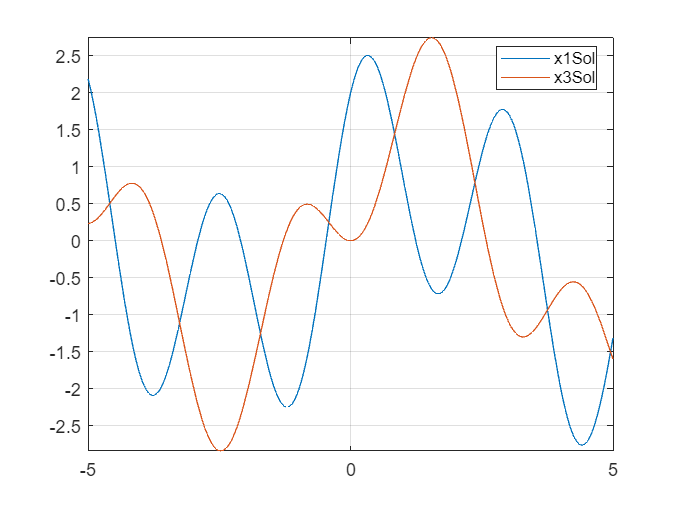

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -4 0 2 0; 0 0 0 1; 2 0 -2 0];
Y = [x1; x2; x3; x4];
odes = diff(Y) == A*Y;
C = [Y(0) == [2;3;0;0;]];
[x1Sol(t),x2Sol(t),x3Sol(t),x4Sol(t)] = dsolve(odes,C);
x1Sol(t) = simplify(x1Sol(t));
x3Sol(t) = simplify(x3Sol(t));
clf
fplot(x1Sol)
hold on
fplot(x3Sol)
grid on
legend('x1Sol','x3Sol','Location','best')